**Model fit**

Let's start again with our miserable fMRI data

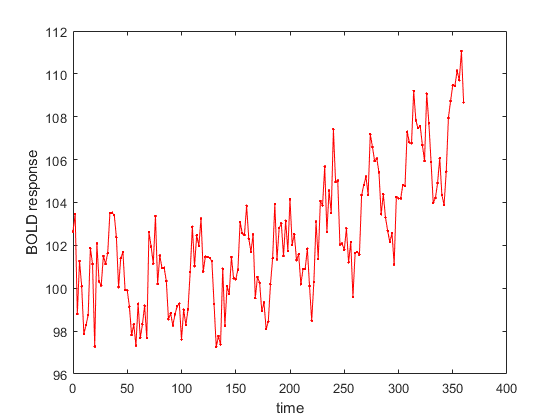

figure()
t_fmri=0:2:360; % data collected every 2s, for 6 min
N = length(t_fmri);
w_fmri=randn(length(t_fmri), 1); % traditional white noise, example 1.8

B0 = 100; 
Bs = 2;
B1 = 0.0001;
zs = reshape(cos((2 * pi*(t_fmri+4))/40), N, 1);
z1 = reshape((t_fmri-70).^2, N, 1);
x=reshape([Bs.*zs + B0 + B1.*z1 + w_fmri], N, 1); 
plot( t_fmri, x, 'r.-'); hold on
xlabel('time'); ylabel('BOLD response');

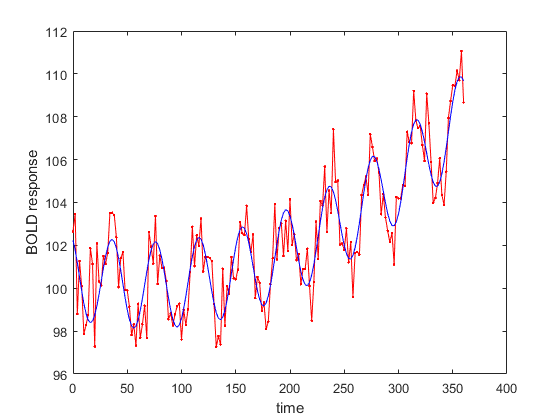

Best = pinv([zs ones(size(zs)) z1])*x;
xest=reshape([Best(1).*zs + Best(2) + Best(3).*z1], N, 1); 
plot(t_fmri, xest, 'b');

But our regressor z2 can be rewritten in the form a + bx + cx2. So we can do the regression as follows.

Best = pinv([ zs ones(size(zs)) t_fmri' t_fmri'.^2])*x;
xest=reshape([Best(1).*zs + Best(2) +  Best(3).*t_fmri' + Best(4).*t_fmri'.^2], N, 1); 
disp('revised version of our regressors')

revised version of our regressors


disp(Best)

    2.0263
  100.9817
   -0.0184
    0.0001



plot(t_fmri, xest, 'c--');

***How many parameters does this model have?***

**A hint of model selection**

Suppose one wanted to decide whether adding the regressor for drift wasa a good idea?

The drift model must perform as well as the non-drift model, because you can always find a B2 value of 0. How do we compare?

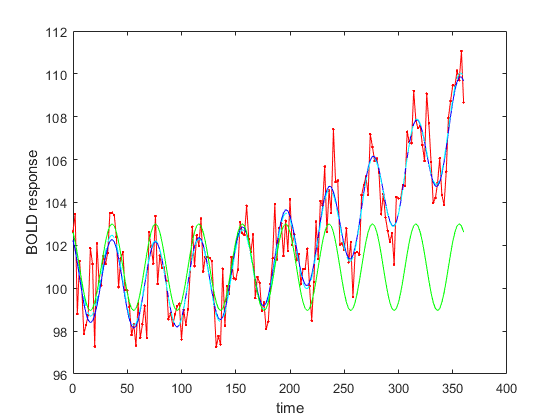

Best_r = pinv([zs ones(size(zs)) ])*x; 
% finding best solution without linear drift
xest_r=reshape([ Best(1).*zs + Best(2)], N, 1); 
plot(t_fmri, xest_r, 'g');


disp('regressors for 1 nonlinear basis function');

regressors for 1 nonlinear basis function


disp(Best_r)

    2.2092
  102.3057



SSE_r = sum((x-xest_r).^2)

SSE_r = 1.5343e+03

SSE = sum((x-xest).^2)

SSE = 218.4666

For this to be a good model the residuals should be iid normal. How would you test this?

## **Birdsong**

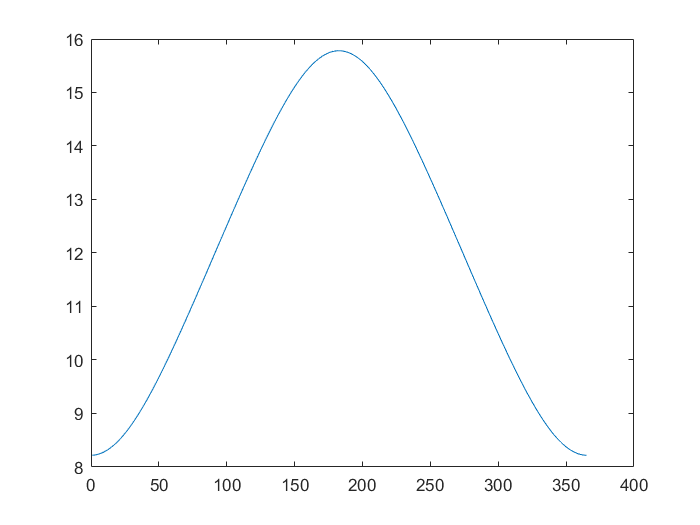


Day=1:365;

Lat_Seattle=(47.6062);%latitude in degrees
%Lat_Seattle=(55.9533);
daylength=day_length(Day,Lat_Seattle);
figure()
plot(Day, daylength);

precip=xlsread('climate_data.xlsx', 'H2:H366')';
temp=xlsread('climate_data.xlsx', 'K2:K366')';

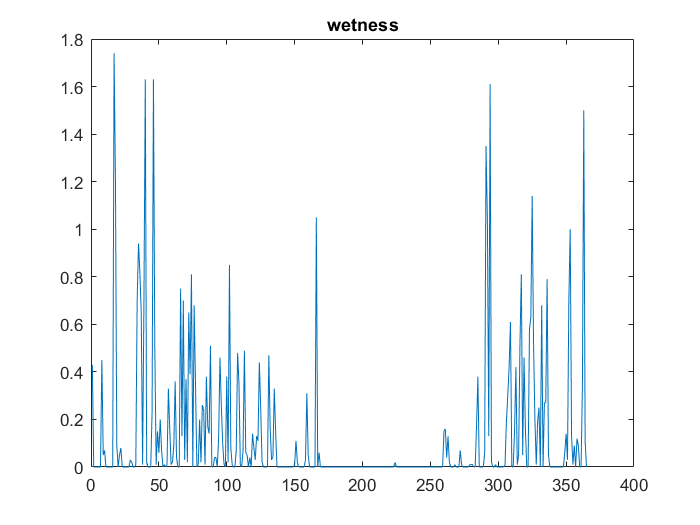


figure()
plot(Day, precip)
title('wetness')

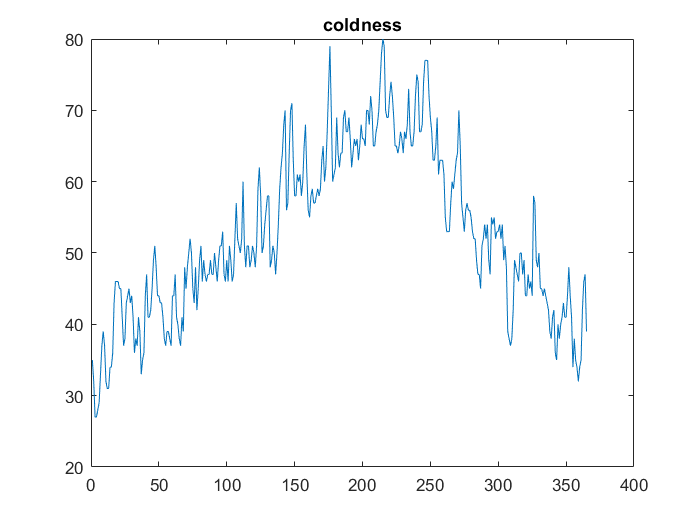


figure()
plot(Day, temp)
title('hotness')

figure()
wt1=randn(1, length(daylength));
wt2=randn(1, length(daylength));
B0=.5; 
B1=.2; % daylength
B2 = 0.005; % temperature
B3=.007; % square of the temperature
B4=1; % precipitation

birdsong1 = B0 + B1.*daylength + B2.*(temp-mean(temp)) +  ...
    B3.*(temp-mean(temp)).^2  + ...
    (B4 .* -1 .* precip) + wt1; 
birdsong2 = B0 + B1.*daylength + B2.*(temp-mean(temp)) +  B3.*(temp-mean(temp)).^2  + ...
    (B4 .* -1 .* precip) + wt2; 



close all
plot(Day, birdsong1, 'g'); hold on
% model 1, full model
pred_birdsong_full= B0 + B1.*daylength + B2.*(temp-mean(temp)) + ...
    B3.*(temp-mean(temp)).^2  + (B4 .* -1 .* precip);  
N = length(daylength);
SSE_full=sum((birdsong1-pred_birdsong_full).^2)

SSE_full = 364.9207

k=4; f=4;
AIC_full = log(SSE_full./N) + (N+2*k)/N

AIC_full = 1.0217

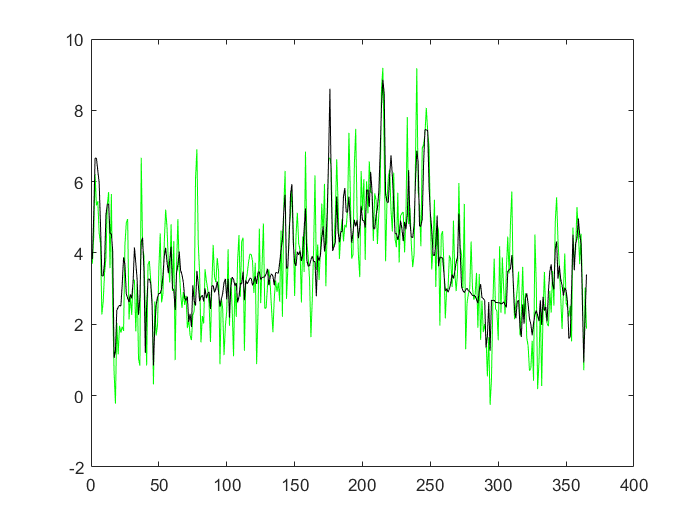

plot(Day, pred_birdsong_full, 'k')

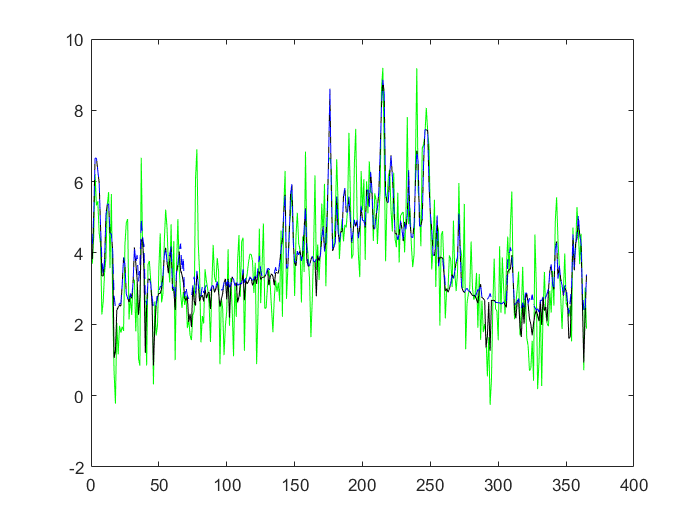


pred_birdsong_noprecip= B0 + B1.*daylength + B2.*(temp-mean(temp)) + ...
    B3.*(temp-mean(temp)).^2;  
SSE_noprecip=sum((birdsong1-pred_birdsong_noprecip).^2);
plot(Day, pred_birdsong_noprecip, 'b--')

k=3;
SSE_noprecip

SSE_full = 364.9207

AIC_noprecip = log(SSE_noprecip./N) + (N+2*k)/N

AIC_noprecip = 1.1476

F = [(SSE_noprecip - SSE_full)./(f-k)]./[ SSE_full./(N-f-k)]

F = 50.2587


pred_birdsong_nodaylength= B0 + 0.*daylength + B2.*(temp-mean(temp)) + ...
    B3.*(temp-mean(temp)).^2  + (0 .* -1 .* precip);  
SSE_nodaylength=sum((birdsong1-pred_birdsong_nodaylength).^2)

SSE_nodaylength = 2.3712e+03

k=3;
AIC_noprecip = log(SSE_nodaylength./N) + (N+2*k)/N

AIC_noprecip = 1.1012

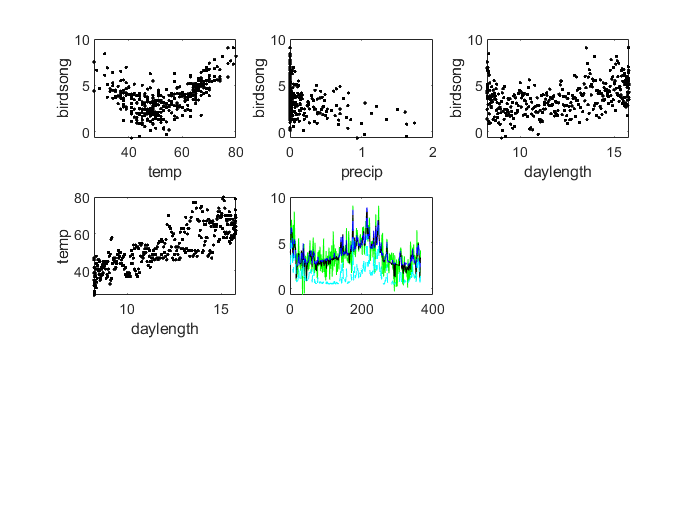

plot(Day, pred_birdsong_nodaylength, 'c--')

F = [(SSE_nodaylength - SSE_full)./(f-k)]./[ SSE_nodaylength./(N-f-k)]

F = 298.0209

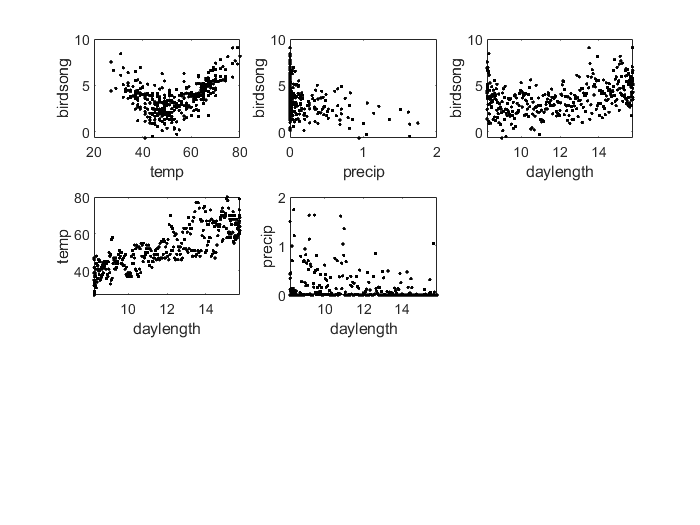


figure()
subplot(3,3, 1); plot(temp, birdsong1, 'k.'); xlabel('temp'); ylabel('birdsong')
subplot(3,3, 2);plot(precip, birdsong1, 'k.'); xlabel('precip'); ylabel('birdsong')
subplot(3,3, 3);plot(daylength, birdsong1, 'k.'); xlabel('daylength'); ylabel('birdsong')
subplot(3,3, 4);plot(daylength, temp, 'k.'); xlabel('daylength'); ylabel('temp')
subplot(3,3, 5);plot(daylength, precip, 'k.'); xlabel('daylength'); ylabel('precip')

## **Model selection**

** (based on how I choose them)**

**Common sense**

Does the model have external validity? 

Imagine if birdsong was inversely related to how much money people spent on toys and the association was highly signifcant. Is that a good model?

One concern about data scence is that the use of big bad networks removes common sense from the model. So in banking one's zipcode can determine the likelihood of credit. Does the number attached to your address determine your credit worthiness. Of course not. It's a proxy for other variables. But bad models can have bad consequences.

**Generalization**

Can the model predict new data? How well? How good is good enough? 

**Is a Linear model appropriate?**

Are residuals normal?

**Model selection statistics (F, Akaike, AIC)**

These models essentially estimate the cost (in terms of SSE) of dropping a parameter. One of the reasons I loathe this entire way of thinking about statistics is that all these tests do is compare two different models. They can both be crap, and one can still be significantly better than the other. If you want to decide between two different models, then they are useful. 

But just because your model won the F-test competition doesn't mean it's a good model. Yet then it's described in the paper as 'the best model'. Sometimes that's like picking the 'best' Republican senator (it's Lisa Murkowski)

**F-test**

This is good for nested models, where one model is simply a more complicated version of another.

N = number data points.

q is the number of parameters in the fuller model

r is the number of paramers in the reduced model

F = [(SSE_r - SSE)./(q-r)]./[ SSE./(N-q-r)]

**AIC**

k os the number of parameters

s2k = SSE/N;

AIC = log(s2k) + (N+2k)/N

***The Rokem test*** 

Is your model as good as the data deserves?

rRMSE = RMSE(M1, D1) + RMSE(M2, D2) / 2RMSE(D1, D2)

If rRMSE is a lot bigger then 1/sqrt(2) then this means either that your noise isn't Gaussian or your model is rubbish.

For the case of IID signals with zero-mean Gaussian noise and standard deviation s

The rMSE has an expected value of 

std(M-D1)+std(M-D2)/std(D1-D2) 

= s/(s*sqrt(2)) 

= 1/sqrt(2)

disp(1/sqrt(2))

    0.7071



Let try it on the full model

rmseM1D1 = mean(sqrt((pred_birdsong_full-birdsong1).^2))

rmseM1D1 = 0.7390

rmseM1D2 = mean(sqrt((pred_birdsong_full-birdsong2).^2))

rmseM1D2 = 0.7843

rmseD1D2 = mean(sqrt((birdsong1-birdsong2).^2))

rmseD1D2 = 1.0548

rokem = (rmseM1D1 + rmseM1D2)./(2.*rmseD1D2)

rokem = 0.7221

Let try it on a reduced model

rmseM1D1 = mean(sqrt((pred_birdsong_nodaylength-birdsong1).^2))

rmseM1D1 = 2.2683

rmseM1D2 = mean(sqrt((pred_birdsong_nodaylength-birdsong2).^2))

rmseM1D2 = 2.1992

rmseD1D2 = mean(sqrt((birdsong1-birdsong2).^2))

rmseD1D2 = 1.0548

rokem = (rmseM1D1 + rmseM1D2)./(2.*rmseD1D2)

rokem = 2.1178

disp(1/sqrt(2))

    0.7071

